

%% Analise da função de transferência Gabruel de Laurentis D Cardoso 18.00477-6
%Gabriel Cardoso 18.00477-6
clear all;
close all;
clc;

%% Definindo as funções de transferência


d1 = 4;
d2 = 7;
d3 = 7;

R = d1+1;
L = d2+1;
C = d3+1;

A1 = R*L

A1 = 40

A2 = R*L*C

A2 = 320


NS = [A1 0];
DS = [A2 L R];
Gs = tf(NS,DS)


Gs =
 
        40 s
  -----------------
  320 s^2 + 8 s + 5
 
Continuous-time transfer function.



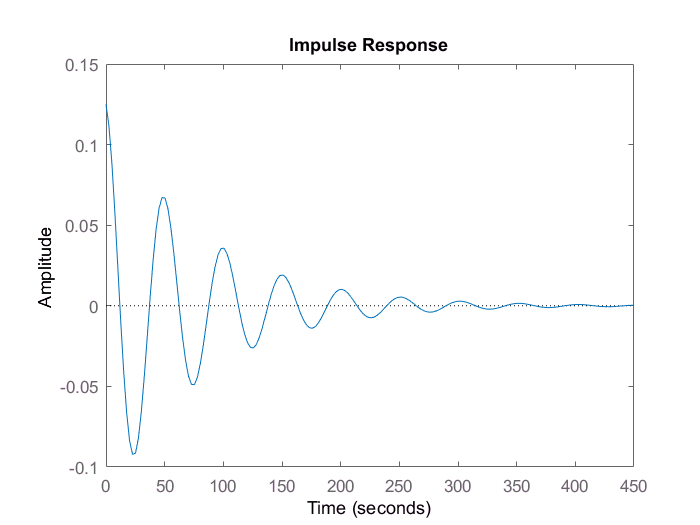

 impulse(Gs);

%% Agora para G(jw)
Gjw = @(w) R*L*j*w./(R*L*C*(j*w).^2 + L*w*j + R)

Gjw =     @(w)R*L*j*w./(R*L*C*(j*w).^2+L*w*j+R)



w = linspace(0,0.3,1000)

w =          0    0.0003    0.0006    0.0009    0.0012    0.0015    0.0018    0.0021    0.0024    0.0027    0.0030    0.0033    0.0036    0.0039    0.0042    0.0045    0.0048    0.0051    0.0054    0.0057    0.0060    0.0063    0.0066    0.0069    0.0072    0.0075    0.0078    0.0081    0.0084    0.0087    0.0090    0.0093    0.0096    0.0099    0.0102    0.0105    0.0108    0.0111    0.0114    0.0117    0.0120    0.0123    0.0126    0.0129    0.0132    0.0135    0.0138    0.0141    0.0144    0.0147


figure()
plot(w,Gjw(w))

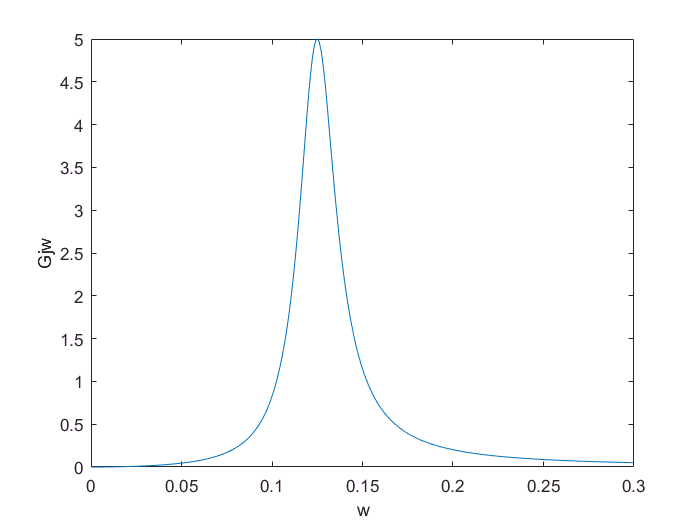

xlabel('w')
ylabel('Gjw')

%Da para ver que e um filtro passa faixa
t = 2*0.25

t = 0.5000

%definindo Ta
Ta = 2*pi/t

Ta = 12.5664


%%Agora para o Gz

%Como mostrado na aula do dia 11/6 utilizaremos o Bilinear
[Nz Dz] = bilinear(NS, DS, Ta)

Nz =     0.0050   -0.0000   -0.0050


Dz =     1.0000   -1.9979    0.9980



Gz = tf(Nz, Dz, Ta)


Gz =
 
  0.004969 z^2 - 2.22e-16 z - 0.004969
  ------------------------------------
         z^2 - 1.998 z + 0.998
 
Sample time: 12.566 seconds
Discrete-time transfer function.



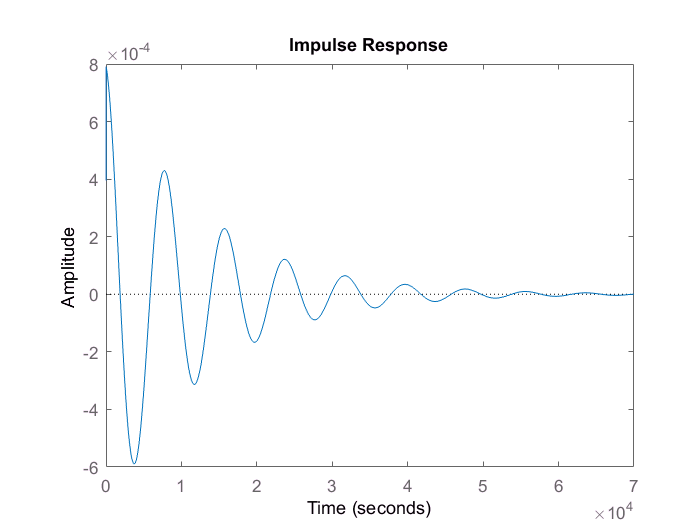

 impulse(Gz)

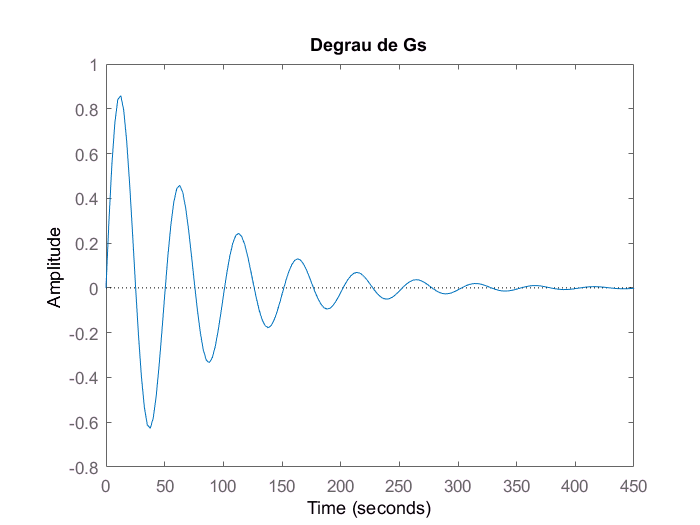

%A resposta impulsiva deu mesmo resultado do Gs

%% Resposta ao degrau Gs Gz

step(Gs)
title('Degrau de Gs')

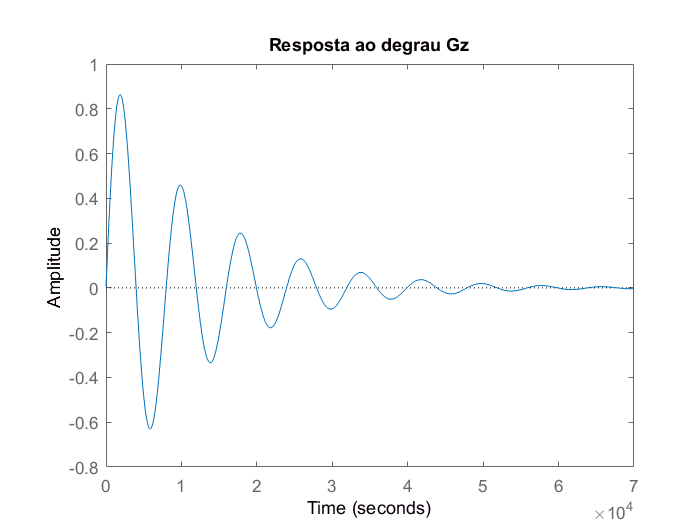

step(Gz)
title('Resposta ao degrau Gz')

Degrau =  @(w) pi .*dirac(w)+  1./j*w

Degrau =     @(w)pi.*dirac(w)+1./j*w


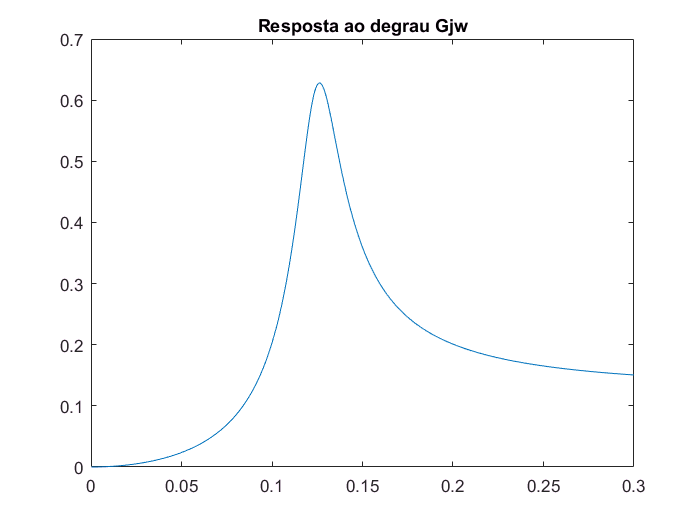

gw = Gjw(w);
degrau = Degrau(w);
pl = degrau .* gw;
plot(w,abs(pl))
title('Resposta ao degrau Gjw')


%% Anlise do audio

[y,Fs] = audioread('Gravação (online-audio-converter.com) (1).wav')

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Fs = 44100

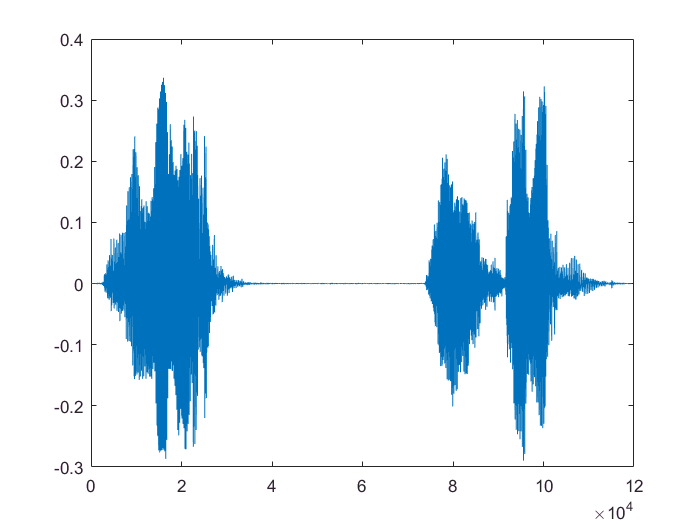


plot(y)


yb = lsim(y, Gz)

yb =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


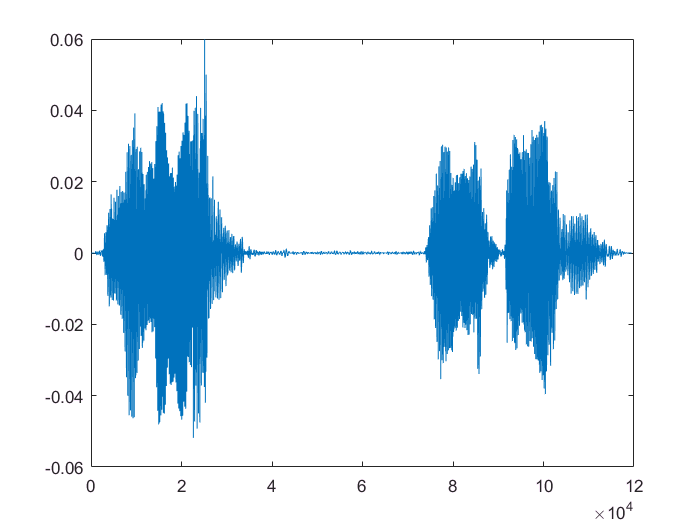

 plot(yb)


 %Podemos ver que o comportamento do Passa faixa remove os sons que não estao no intervalo de frequencia de fourier
 
 %% sistema LIT
 T = linspace(0,100,1000)

T =          0    0.1001    0.2002    0.3003    0.4004    0.5005    0.6006    0.7007    0.8008    0.9009    1.0010    1.1011    1.2012    1.3013    1.4014    1.5015    1.6016    1.7017    1.8018    1.9019    2.0020    2.1021    2.2022    2.3023    2.4024    2.5025    2.6026    2.7027    2.8028    2.9029    3.0030    3.1031    3.2032    3.3033    3.4034    3.5035    3.6036    3.7037    3.8038    3.9039    4.0040    4.1041    4.2042    4.3043    4.4044    4.5045    4.6046    4.7047    4.8048    4.9049


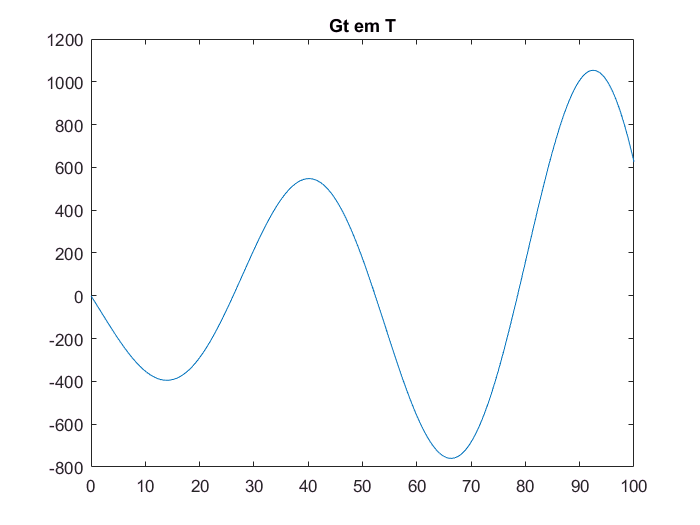

 Gt = 40 .* heaviside(T) ./ (0.24 .* j).* (exp((0.0125.*T-0.12.*j.*T))-exp((0.0125.*T+0.12.*j.*T)));
 plot(T,Gt)
 title('Gt em T')

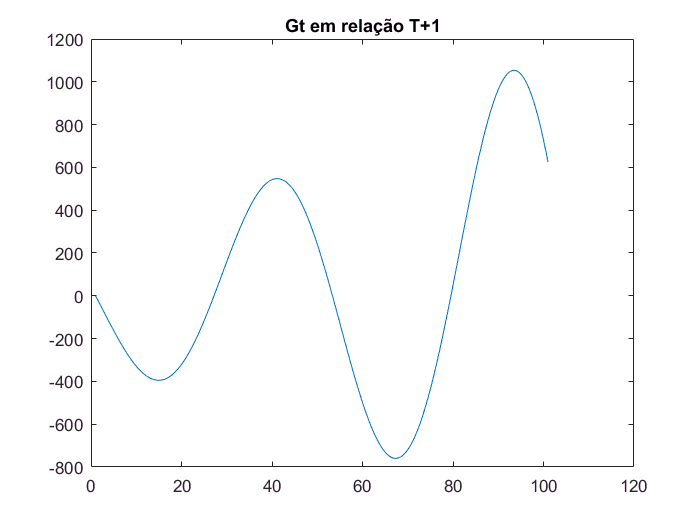

 plot((T+1),Gt)
 title('Gt em relação T+1')

 %Pela não alteração dos gráficos podemos concluir qué LIT